## Cleaning

clear
clc

## Declare Variables

% Constant variables
altitude = 25000; % Desired altitude of 25000 m
payloadMass = 500; % Desired payload mass of 500 kg
FS = [1:1:100]'; % Self-selected number in range 1:5
Pgage = 10; % Gage pressure in Pa
gravity = 9.81; % Acceleration of gravity in m / s^2

% Variable variables (o_o )
    % Measurements based on information found in:
    % http://www.matweb.com/search/datasheet_print.aspx?matguid=bcd1ad1e1a7445aca5321d26f00bdf12
materialThickness = 3.81 * 10^-5; % Balloon material thickness in m
YS = 15.5 * 10^6; % Yield strength of balloon material in Pa
materialDensity = 924; % Density of material in kg / m^3
gasConst = 8.31e3 % Gas constant for Helium in kJ / kg*K

gasConst = 8310


% Create table for data
data = table(FS, 'VariableNames', {'FactorSafety'})

data = 100×1 table
    FactorSafety
    ____________

          1     
          2     
          3     
          4     
          5     
          6     
          7     
          8     
          9     
         10     
         11     
         12     
         13     
         14     
         15     
         16     


## Declare equations

% Calculate sphere volume given radius
sphereVol = @(r) (4/3) * pi * (r.^3)

sphereVol = function_handle with value:
    @(r)(4/3)*pi*(r.^3)



% Calculate yield strength given factor of safety, gage pressure, radius,
% and thickness
yieldStrength = @(F_S, Pgage, r, t) (F_S .* (Pgage * r)) ./ (2 * t)

yieldStrength = function_handle with value:
    @(F_S,Pgage,r,t)(F_S.*(Pgage*r))./(2*t)



% Calculate stress given gage pressure, radius, and thickness
stress = @(Pgage, r, t) (Pgage * r) / (2 * t)

stress = function_handle with value:
    @(Pgage,r,t)(Pgage*r)/(2*t)



% Calculate radius given density of air, pressure of air, factor of safety,
% yield strength of material, and temperature
radius = @(denAir, pressureAir, FS, YS, temp) abs(payloadMass ./ ( ((4/3) * denAir * pi) - (((materialDensity * 2 * pi * Pgage) .* FS) ./ YS) - ( ((pressureAir * 4 * pi) / ((3 * gasConst) .* temp))) )) .^ (1/3)

radius = function_handle with value:
    @(denAir,pressureAir,FS,YS,temp)abs(payloadMass./(((4/3)*denAir*pi)-(((materialDensity*2*pi*Pgage).*FS)./YS)-(((pressureAir*4*pi)/((3*gasConst).*temp))))).^(1/3)



% Calculate buoyancy force given fluid density, gravity, and volume
buoyancy = @(density, volume) density * gravity * volume

buoyancy = function_handle with value:
    @(density,volume)density*gravity*volume



% Calculate force of gravity given mass
weight = @(mass) mass * gravity

weight = function_handle with value:
    @(mass)mass*gravity



thick = @(FS, radius) (FS .* Pgage .* radius) ./ (2 .* YS);

## Calculate approximate balloon radius

bisonTopSpeed = 35 * 0.44704 % m/s

bisonTopSpeed = 15.6464

## Begin calculations

% Find atmospheric conditions based on 1976 model
[temp, speedSound, pressure, densityAir] = atmoscoesa(altitude)

temp = 221.6500

speedSound = 298.4551

pressure = 2.5110e+03

densityAir = 0.0395


% Find radius of balloon 
data.balloonRadius = radius(densityAir, pressure, data.FactorSafety, YS, temp); % Radius in m

% Find volume of balloon
data.balloonVolume = sphereVol(data.balloonRadius); % Volume in m^3

% Find buoyancy force
data.forceBuoyancy = buoyancy(densityAir, data.balloonVolume); % Buoyancy force in N

% Find force of gravity (weight of balloon)
data.thickness = thick(data.FactorSafety, data.balloonRadius); % Thickness in m
data.amtBalloonMaterial = data.balloonVolume - sphereVol(data.balloonRadius - data.thickness); % m^3
data.massHeFBE = (densityAir * data.balloonVolume) - payloadMass - (materialDensity * data.amtBalloonMaterial); % Mass of He in kg
data.totalMass = (data.amtBalloonMaterial * materialDensity) + payloadMass + data.massHeFBE; % Total mass of the system in kg
data.forceGravity = weight(data.totalMass); % Force of gravity of the system in N --> should be equal to the force of buoyancy

% Find mass of He from PV=nRT equation
massHePVNRT = (pressure .* data.balloonVolume) ./ (gasConst * temp);

## Find effects of temperature change

% Given values
alpha_sb = 0.6;
epsilon_b = 0.8;
alpha_eb = epsilon_b;
q_sun = 1353; % W / m^2
q_earth = 237; % W / m^2

% Find atmospheric properties at high and low altitudes
    % Need to take into account pressure and density variations at the
    % altitudes above and below the mean altitude
% [~, speedSoundMax, pressureMax, densityAirMax] = atmoscoesa(altitude + 1000) % Find atmospheric information at max altitude
% [~, speedSoundMin, pressureMin, densityAirMin] = atmoscoesa(altitude - 1000) % Find atmospheric information at min altitude

% Calculate max and min temperatures
data.Q_dot_solar = (alpha_sb * q_sun * pi) .* (data.balloonRadius .^ 2); % Change in thermal energy of the sun in W
data.Q_dot_earth = (alpha_eb * q_earth * pi) .* (data.balloonRadius .^ 2); % Change in  thermal energy of the earth in W
Tday = ( (data.Q_dot_solar + data.Q_dot_earth) ./ ( (4 * pi * 5.67e-8 * .8) * (data.balloonRadius .^ 2) ) ) .^ (1/4); % Max temperature in K
Tnight = ( data.Q_dot_earth ./ ( (4 * pi * 5.67e-8 * .8) * (data.balloonRadius .^ 2) ) ) .^ (1/4); % Min temperature in K
Tday = Tday(1)

Tday = 272.5641

Tnight = Tnight(1)

Tnight = 179.7945


newVolDay = data.massHeFBE ./ (densityAir - ((temp * (payloadMass + data.amtBalloonMaterial)) ./ (Tday * data.balloonVolume)))

newVolDay = 	1.0e+06 *

    0.0020
    0.0019
    0.0018
    0.0017
    0.0017
    0.0016
    0.0016
    0.0015
    0.0015
    0.0015


newVolNight = data.massHeFBE ./ (densityAir - ((temp * (payloadMass + data.amtBalloonMaterial)) ./ (Tnight * data.balloonVolume)))

newVolNight = 	1.0e+06 *

   -0.0029
   -0.0035
   -0.0046
   -0.0064
   -0.0101
   -0.0231
    0.1063
    0.0169
    0.0094
    0.0067



% volumeDay = ((data.totalMass * gasConst * Tday) / pressure)
% volumeNight = ((data.totalMass * gasConst * Tnight) / pressure)
% testVolDay = sphereVol(radius(densityAir, pressure, data.FactorSafety, YS, Tday))
% testVolNight = sphereVol(radius(densityAir, pressure, data.FactorSafety, YS, Tnight))
out = data.balloonVolume

out = 	1.0e+06 *

    0.0134
    0.0138
    0.0141
    0.0145
    0.0149
    0.0153
    0.0157
    0.0162
    0.0166
    0.0171


% densityHeDay = data.massHeFBE./ volumeDay
% densityHeNight = data.massHeFBE ./ volumeNight
% densityBase = data.massHeFBE ./ data.balloonVolume

data

data = 100×11 table
    FactorSafety    balloonRadius    balloonVolume    forceBuoyancy    thickness     amtBalloonMaterial    massHeFBE    totalMass    forceGravity    Q_dot_solar    Q_dot_earth
    ____________    _____________    _____________    _____________    __________    __________________    _________    _________    ____________    ___________    ___________

          1            14.748            13438           5202.6        4.7576e-06         0.013004          18.319       530.34         5202.6       5.5474e+05     1.2956e+05 
          2            14.869            13769           5330.7        9.5926

## Useless junk

% % Calculate effects of max and min temperatures on balloon properties
%     % The balloon is only allowed to stray 1 km above or below the 25 km
%     % mark, so calculations need to be based on that assumption.
%     % This will help us figure out how much weight we need for the balloon
%     % to stay in that region
% data.balloonVolumeTmax = sphereVol(radius(densityAirMax, pressureMax, data.FactorSafety, YS, Tday)); % Volume of balloon at max temperature in m^3
% data.balloonVolumeTmin = sphereVol(radius(densityAirMin, pressureMin, data.FactorSafety, YS, Tnight)); % Volume of balloon at min temperature in m^3
% data.forceBuoyancyMax = buoyancy(densityAirMax, data.balloonVolumeTmax); % Calculate buoyancy force of balloon at maximum temperature in N
% data.forceBuoyancyMin = buoyancy(densityAirMin, data.balloonVolumeTmin); % Calculate buoyancy force of balloon at minimum temperature in N
% 
% % Find the differences in buoyancy force vs force of gravity for max and
% % min temperatures
% diffMax = data.forceBuoyancyMax - data.forceGravity % Difference between buoyancy force and force of gravity for Tmax
% diffMin = data.forceBuoyancyMin - data.forceGravity % Difference between buoyancy force and force of gravity for Tmin
% 
% % Calculate weight needed for neutral buoyancy at max and min temperatures
% data.totalMassTmax = data.forceBuoyancyMax / gravity; % Mass neeeded for neutral buoyancy at Tmax in kg
% data.totalMassTmin = data.forceBuoyancyMin / gravity; % Mass neeeded for neutral buoyancy at Tmin in kg
% data.ballastMass = data.totalMassTmax - data.totalMassTmin; % Ballast mass that must be removed during flight in kg
% 
% massMeetsRequirementsIdx = (data.totalMassTmax - data.massHeFBE - (materialDensity * data.amtBalloonMaterial)) >= 500
% currectFactorSafety = data.FactorSafety(massMeetsRequirementsIdx)
% 
% massDiffMax = data.totalMassTmax - payloadMass - data.massHeFBE - (materialDensity * data.amtBalloonMaterial) % Difference in mass between what we need and what we have
% massDiffMin = data.totalMassTmin - payloadMass - data.massHeFBE - (materialDensity * data.amtBalloonMaterial) % Difference in mass between what we need and what we have

## Graphs of features vs Factor of Safety

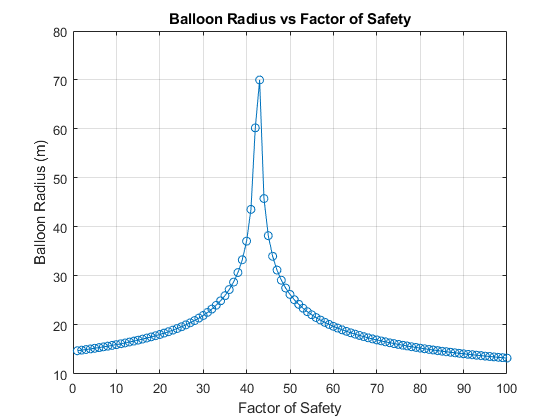

plot(data.FactorSafety, data.balloonRadius, 'o-')
grid on
title("Balloon Radius vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Radius (m)")

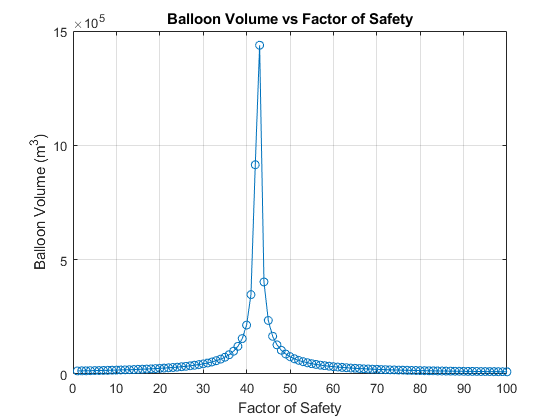


plot(data.FactorSafety, data.balloonVolume, 'o-')
grid on
title("Balloon Volume vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Volume (m^3)")

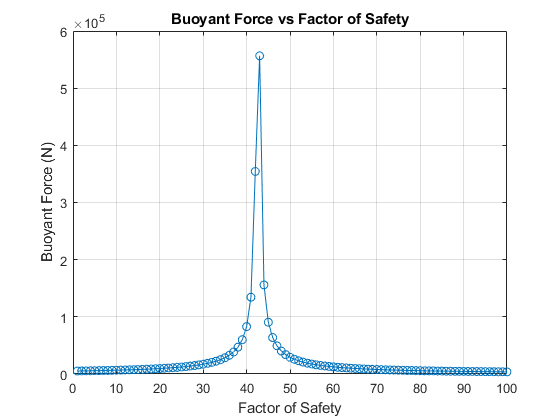


plot(data.FactorSafety, data.forceBuoyancy, 'o-')
grid on
title("Buoyant Force vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Buoyant Force (N)")

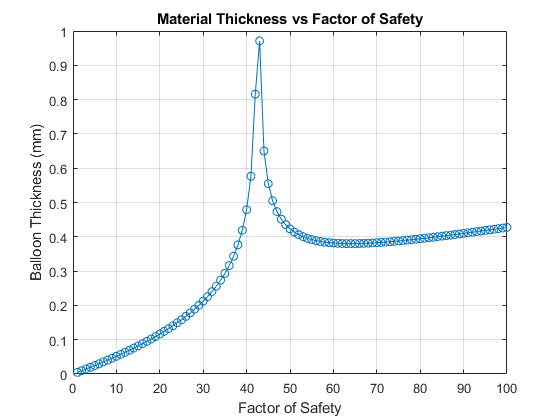


plot (data.FactorSafety, data.thickness .* 1000, 'o-')
grid on
title("Material Thickness vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Thickness (mm)")